%% STEP 1: Load and Prepare Data
load('India_Emissions_Cleaned.mat','india_linear');

IndiaData = india_linear(:,{'Year','Total'});
IndiaData.Year = datetime(IndiaData.Year,1,1);

IndiaTT = table2timetable(IndiaData,'RowTimes','Year');

splitYear = datetime(2018,1,1);
trainData = IndiaTT(IndiaTT.Year < splitYear,:);
testData  = IndiaTT(IndiaTT.Year >= splitYear,:);

fprintf('Training observations: %d\n', height(trainData));

Training observations: 160


fprintf('Testing observations:  %d\n', height(testData));

Testing observations:  6



%% STEP 2: Log Transformation
trainData.logTotal = log(trainData.Total + 1);
testData.logTotal  = log(testData.Total + 1);

%% STEP 3: Cubic Detrending (TRAINING ONLY)
cubicDetrended = detrend(trainData(:,"logTotal"),3);

cubicTrend = trainData(:,"logTotal");
cubicTrend.logTotal = cubicTrend.logTotal - cubicDetrended.logTotal;

cubicRemainder = cubicDetrended.logTotal;

%% STEP 4: Stationarity Check
[h,p] = adftest(cubicRemainder);
fprintf('ADF test on detrended series: h=%d, p=%.4f\n',h,p);

ADF test on detrended series: h=1, p=0.0386



%% STEP 5: Decomposition Plot
figure;
subplot(3,1,1)
plot(trainData.Year,trainData.logTotal,'k','LineWidth',1.2)
title('Log-Transformed Emissions'); grid on

subplot(3,1,2)
plot(trainData.Year,cubicTrend.logTotal,'b','LineWidth',1.2)
title('Cubic Trend'); grid on

subplot(3,1,3)
plot(trainData.Year,cubicRemainder,'r','LineWidth',1.2)
yline(0,'k--'); title('Detrended Residuals'); grid on

sgtitle('India CO₂ Emissions — Cubic Decomposition')

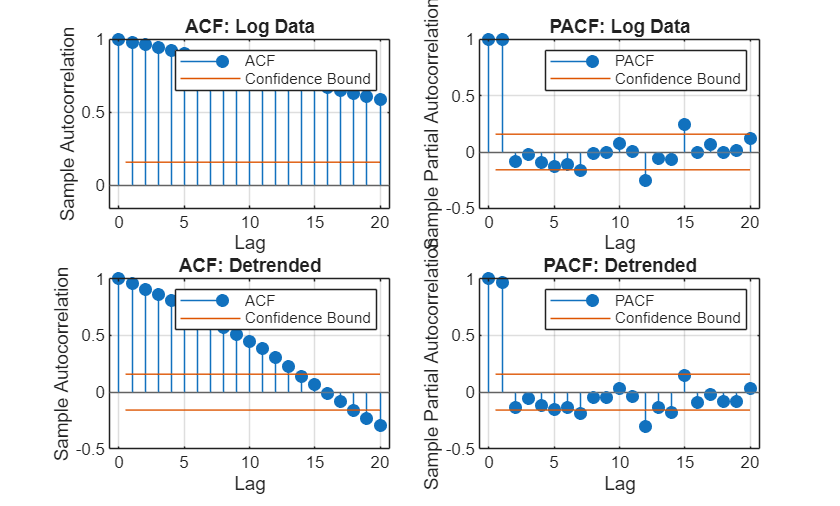


%% STEP 6: ACF / PACF
figure;
subplot(2,2,1); autocorr(trainData.logTotal); title('ACF: Log Data')
subplot(2,2,2); parcorr(trainData.logTotal); title('PACF: Log Data')
subplot(2,2,3); autocorr(cubicRemainder); title('ACF: Detrended')
subplot(2,2,4); parcorr(cubicRemainder); title('PACF: Detrended')


%% STEP 7: ARIMA Grid Search (on detrended series)
arVals = 1:7;
maVals = 0:3;
results = [];

for ar = arVals
    for ma = maVals
        try
            mdl = arima(ar,0,ma);
            fit = estimate(mdl,cubicRemainder,'Display','off');
            [~,~,logL] = infer(fit,cubicRemainder);
            logL = sum(logL);

            numParams = numel(fit.AR) + numel(fit.MA) + 2;
            [aic,bic] = aicbic(logL,numParams,length(cubicRemainder));

            results = [results; ar ma aic bic];
        catch
        end
    end
end

resultsTbl = array2table(results, ...
    'VariableNames',{'AR','MA','AIC','BIC'});
resultsTbl = sortrows(resultsTbl,'AIC');

bestAR = resultsTbl.AR(1);
bestMA = resultsTbl.MA(1);
fprintf('Best model: ARIMA(%d,0,%d)\n',bestAR,bestMA);

Best model: ARIMA(6,0,3)



bestModel = estimate(arima(bestAR,0,bestMA), ...
                     cubicRemainder,'Display','off');

%% STEP 8: TRAINING FIT (evaluation only)
T = height(trainData);
[arimaTrain,~] = forecast(bestModel,T,cubicRemainder);

logTrainFit = cubicTrend.logTotal + arimaTrain;
trainFit = exp(logTrainFit) - 1;

trainRMSE = sqrt(mean((trainFit - trainData.Total).^2));
fprintf('Training RMSE: %.4f\n',trainRMSE);

Training RMSE: 69.5366



%% STEP 9: TEST FORECAST (evaluation only)
h = height(testData);

t_train = (1:T)';
pLin = polyfit(t_train,cubicTrend.logTotal,1);   % linear trend

trendTest = polyval(pLin,(T+1:T+h)');
[arimaTest,~] = forecast(bestModel,h,cubicRemainder);

logTestForecast = trendTest + arimaTest;
testForecast = exp(logTestForecast) - 1;

testRMSE = sqrt(mean((testForecast - testData.Total).^2));
fprintf('Test RMSE: %.4f\n',testRMSE);

Test RMSE: 773.3524



%% STEP 10: FINAL MODEL TO 2050 USING LOG-GROWTH ARIMA
% Refit using ALL observed data, but model growth (diff of log) not level.

allData = IndiaTT;
allData.logTotal = log(allData.Total + 1);

% Growth rate (log differences)
g = diff(allData.logTotal);

% Fit ARIMA on growth rates (start simple; you can grid search p/q if desired)
% A good starting point is ARIMA(1,0,1) or ARIMA(2,0,2)
growthModel = estimate(arima(1,0,1), g, 'Display','off');

% Forecast growth rates to 2050
futureYears = (year(allData.Year(end))+1:2050)';
H = numel(futureYears);

[gF, gMSE] = forecast(growthModel, H, g);

% Reconstruct future log-levels by accumulating growth from last observed logTotal
lastLog = allData.logTotal(end);
logFuture = lastLog + cumsum(gF);

% Optional: include uncertainty (approx) by accumulating variance
% (simple approximation; good enough for class projects)
logVar = cumsum(gMSE);
logLo = logFuture - 1.96*sqrt(logVar);
logHi = logFuture + 1.96*sqrt(logVar);

% Back-transform
futureForecast = exp(logFuture) - 1;
lo = exp(logLo) - 1;
hi = exp(logHi) - 1;

%% STEP 11: Final Visualization
figure; hold on;
plot(trainData.Year,trainData.Total,'k','LineWidth',1.3)
plot(testData.Year,testData.Total,'r','LineWidth',1.3)

% Test forecast from Step 9
plot(testData.Year,testForecast,'b','LineWidth',1.4)

% 2050 forecast
plot(datetime(futureYears,1,1),futureForecast,'m--','LineWidth',1.5)
plot(datetime(futureYears,1,1),lo,'m:','LineWidth',1)
plot(datetime(futureYears,1,1),hi,'m:','LineWidth',1)

legend('Actual Training','Actual Testing','Predicted (Test)','2050 Forecast','95% Interval','Location','best')
xlabel('Year'); ylabel('CO₂ Emissions')
title('India CO₂ Emissions Forecast to 2050 (ARIMA on Log-Growth)')
grid on; hold off